TIK_st.name='TIK'; 
TIK_st.lat=71.59;
TIK_st.lon=128.92;
TIK_st.alt=8;
TIK_st.env='P';
TIK_st.footp='RB';

TIK_rd=read_betsy('tik_2009_2018',TIK_st.name);

datevec(TIK_rd.Time(1))

ans =         2009           9          30           0           0           0


datevec(TIK_rd.Time(end))

ans =         2018          10          23           0           0           0


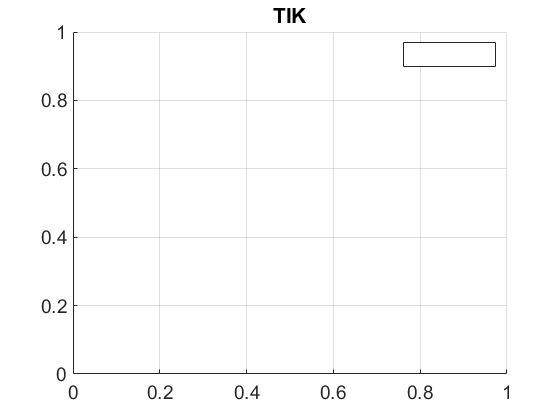

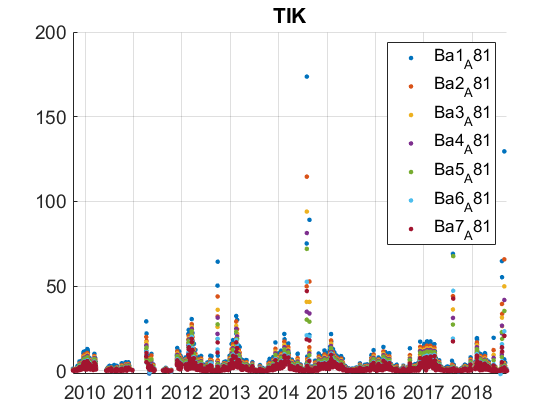

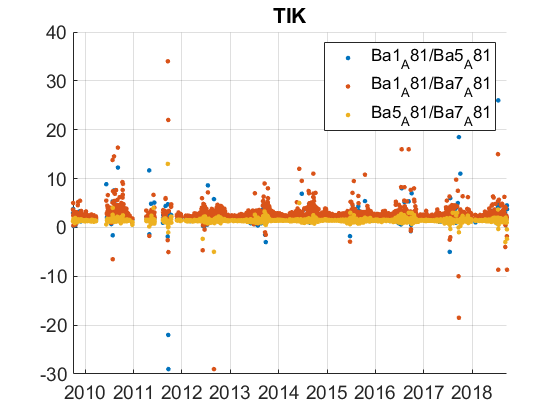

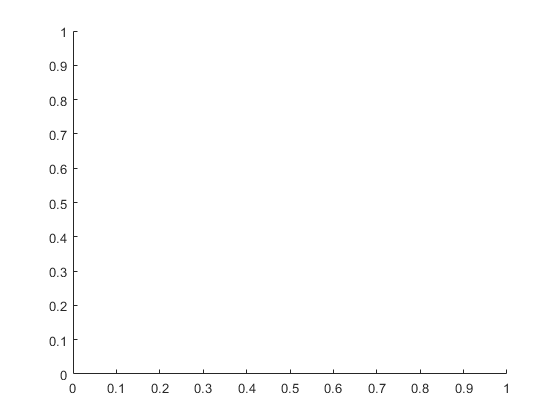

%prctile(TIK_rd.U_S,[5 50 95])
plotFigControl(TIK_rd,TIK_st.name);

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
TIK_cal=compute_exp_SSA(TIK_rd,lambdaSC, lambdaAE);

SCexclus = 70

ans = 19

ans = 754

ans = 0

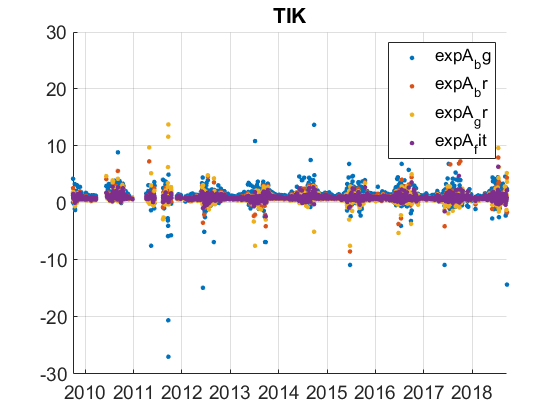

plotFigControl_cal(TIK_cal, TIK_st.name);

TIK_tr=TIK_rd; 
TIK_tr.y=year(TIK_tr.Time);
% scat begin at the beginning of a year: 2010
%end: 23 october 2018 --> 9y (begin end of september, if all is taken it
%makes a complete year --> take all

%P=timerange('2006-01-01','2019-01-01');
%TIK_tr=TIK_tr(P,:);

% no U, only AE31 from NOAA
names=fieldnames(TIK_tr);
c= startsWith(names,["X"]);
N=names(c);
for i=1:length(N)
    TIK_tr.(N{i})=[];
end
TIK_cal2=TIK_cal;
TIK_tr=outerjoin(TIK_tr, TIK_cal2);
%compute trend only on Ba3 and fit

TIK_tr.Ba1_A81=[];
TIK_tr.Ba2_A81=[];
TIK_tr.Ba4_A81=[];
TIK_tr.Ba5_A81=[];
TIK_tr.Ba6_A81=[];
TIK_tr.Ba7_A81=[];

TIK_tr.expA_bg=[];
TIK_tr.expA_br=[];
TIK_tr.expA_gr=[];

TIK_result=all_trend_STN(TIK_tr,TIK_st);

TIK_result_D=TIK_result;